clear all;
close all;
clc;

set(0,'defaultaxeslinewidth',1.5);
set(0,'defaultlinelinewidth',1.5);
set(0,'DefaultAxesFontSize', 12);

load('simulated_data1'); % Loading saved dynamic data from simulation with split ratio 60-20-20

%% split the data to training, validation and testing, including the reference data
%% Training sets
train_data_gyr      = num2cell(g_xup(1:split_idx_train, :),1);
train_labels_omeg   = num2cell(labels_omeg(1:split_idx_train, :),1);

%% Validation sets
val_data_gyr        = num2cell(g_xup(split_idx_train+1:split_idx_val, :),1);
val_labels_omeg     = num2cell(labels_omeg(split_idx_train+1:split_idx_val, :),1);

%% Testing sets
test_data_gyr       = num2cell(g_xup(split_idx_val+1:end, :),1);
test_labels_omeg    = num2cell(labels_omeg(split_idx_val+1:end, :),1);

%% since I need my input size to the NN to be 1, I need to change the
%% appearance of the cell array, where each cell of both data & labels
%% to be 1xsplit_idx & 1xsplit_id+1:end respectively

for k = 1:num_train_seq
    train_data_gyr{k}       = train_data_gyr{k}';
    train_labels_omeg{k}    = train_labels_omeg{k}';

    val_data_gyr{k}         = val_data_gyr{k}';
    val_labels_omeg{k}      = val_labels_omeg{k}';
        
    test_data_gyr{k}        = test_data_gyr{k}';
    test_labels_omeg{k}     = test_labels_omeg{k}';
end

train_data     = train_data_gyr;
train_labels   = train_labels_omeg;

val_data       = val_data_gyr;
val_labels     = val_labels_omeg;

test_data      = test_data_gyr;
test_labels    = test_labels_omeg;

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.92 |         0.61 |       0.4264 |       0.1874 |          0.0010 |
|       1 |          50 |       00:00:07 |         0.18 |         0.23 |       0.0170 |       0.0255 |          0.0010 |
|       2 |         100 |       00:00:09 |         0.08 |         0.07 |       0.0028 |       0.0022 |          0.0010 |
|       3 |         150 |       00:00:10 |         0.03 |         0.06 |       0.0005 |       0.0015 |          0.0010 |
|       

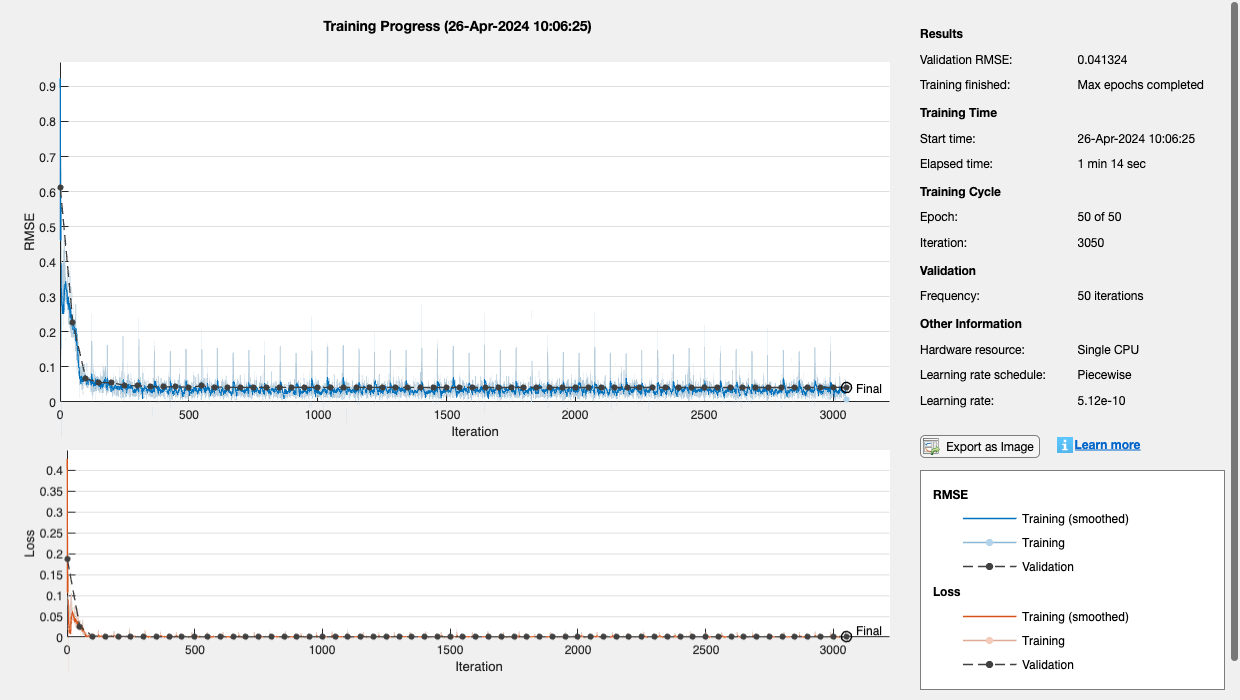

% configure neural network (NN)
numFeatures     = size(train_data, 1); % Number of features in your data
numHiddenUnits  = 90; % Adjust as needed
numResponses    = 1;

layers = [
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits, 'OutputMode', 'sequence')
    dropoutLayer(0.2)
    tanhLayer
    fullyConnectedLayer(numResponses)
    regressionLayer 
];

% Set training options with the Adam optimizer
options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 2^10, ...
    'SequenceLength', 10, ... % Adjust as needed
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.001, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.2, ...
    'LearnRateDropPeriod', 5, ...
    'Shuffle', 'every-epoch', ...  % to reduce biases in training
    'ValidationData', {val_data, val_labels}, ...
    'ExecutionEnvironment', 'auto', ...
    'Plots','training-progress',...
    'Verbose',1);

% Train the LSTM network
net = trainNetwork(train_data, train_labels, layers, options);

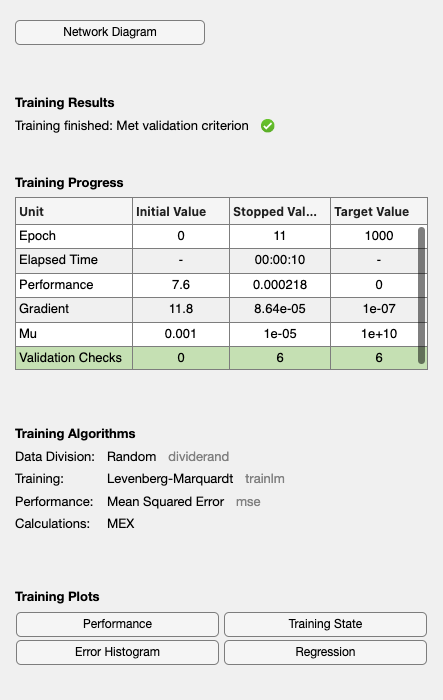


% Test the trained network
predicted_labels = predict(net, test_data);
predicted_labels = predicted_labels';

% Put the output into the fitting tool app
g_lstm          = predicted_labels;
gyr_ref         = gyr_ref(split_idx_val+1:end)';

% Choose a Training Function
trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation.

% Create a Fitting Network
hiddenLayerSize         = 60;
net                     = feedforwardnet(hiddenLayerSize,trainFcn); % feed forward

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio  = 60/100;
net.divideParam.valRatio    = 20/100;
net.divideParam.testRatio   = 20/100;

% Train the Networks
[netgyr,tr_gyr] = train(net,g_lstm,gyr_ref);


% Test the Networks
gyr_netfit          = netgyr(g_lstm);
e_gyr               = gsubtract(gyr_ref,gyr_netfit);
mse_gyr             = perform(netgyr,gyr_ref,gyr_netfit)

mse_gyr = 0.0027

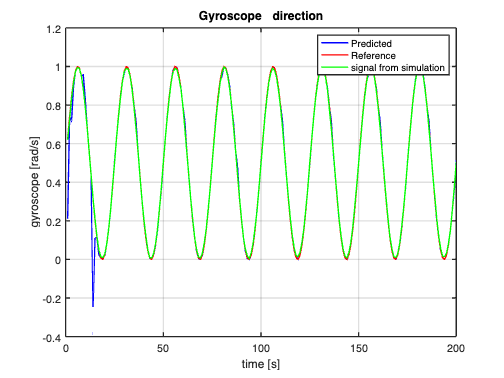


% PLOTS
% plot for gyroscope
aa_g = g_xup(split_idx_val+1:end);
aa_g = aa_g';
fig1=figure;
plot(gyr_netfit{:},'b');
hold on;
plot(gyr_ref, 'r');
plot(aa_g,'g');
grid on
xlabel('time [s]');
ylabel('gyroscope [rad/s]');
legend('Predicted','Reference','signal from simulation');
title('Gyroscope _ direction');
exportgraphics(fig1,'Gyroscope _ direction.png','Resolution',300);

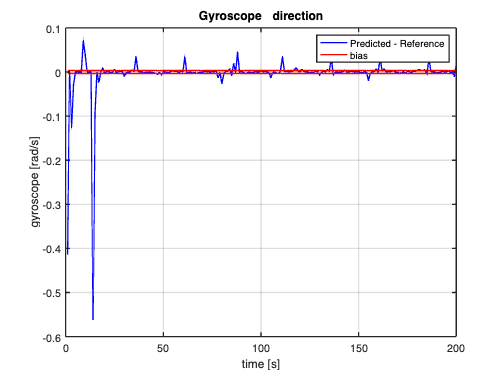


delta_g = gyr_netfit{:}-gyr_ref;
bias_gyro = repelem(bias_gyro,f_imu);
fig2=figure;
plot(delta_g,'b');
hold on
plot(bias_gyro,'r');
plot(-1*bias_gyro,'r');
grid on
xlabel('time [s]');
ylabel('gyroscope [rad/s]');
legend('Predicted - Reference','bias');
title('Gyroscope _ direction');
exportgraphics(fig2,'Gyroscope Predicted - Reference.png','Resolution',300);